**Read in the members from the kml provided by Google Earth**

m_read_kml

kml_file = 'Simple Topographical Features.kml'

**Find the closest pxids to the extrapolated points**

load('ancillary_mat/modis_qkm_pixel_latlon.mat')
m_focal_pxids = double.empty;
for i = 1:m_scene_count
    m_focal_pxids(i) = gcd(m_latlons{1,i}, modis_qkm_pixel_lat, modis_qkm_pixel_lon, r, c);
end
clearvars -regexp modis_;  
clearvars c r i;
save('run/m_focal_pxids.mat', 'm_focal_pxids');

**Initialize cell array to hold all MXVI data by year and insert mxvi vals in seperate matrices**

mxvi_cell_arr

**Generate MXVI **

load('ancillary_mat/modis_qkm_water_mask.mat');
m_mxvi_subset1 = cell(m_year_count, m_scene_count);
m_mxvi_subset2 = cell(m_year_count, m_scene_count);
m_mxvi_subset3 = cell(m_year_count, m_scene_count);
for i = 1:m_year_count
    cur_mxvi = mxvi_vals{i, 1};
    for j = 1:m_scene_count
        cur_focal_pxid = m_focal_pxids(j);
        m_mxvi_subset1{i, j} = mxvi_subset(cur_focal_pxid, cur_mxvi, water1_land0, 400, 400, c);
        m_mxvi_subset2{i, j} = mxvi_subset(cur_focal_pxid, cur_mxvi, water1_land0, 200, 200, c);
        m_mxvi_subset3{i, j} = mxvi_subset(cur_focal_pxid, cur_mxvi, water1_land0, 40, 40, c);
    end
end
clearvars water1_land0 pxid_modis_land c r;

** Create matlab figures for each of the subset scenes**

cur_name = "Black Canyon of the Gunnison cur_year  (MXVI)"

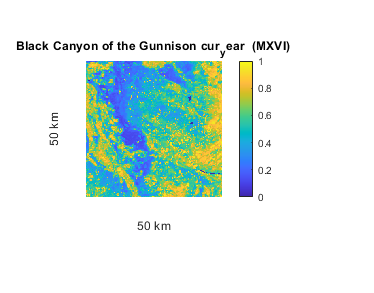

cur_name = "Gunnison Point cur_year  (MXVI)"

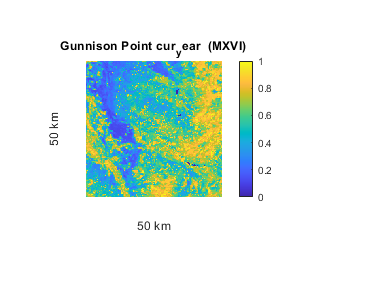

cur_name = "Marble Canyon cur_year  (MXVI)"

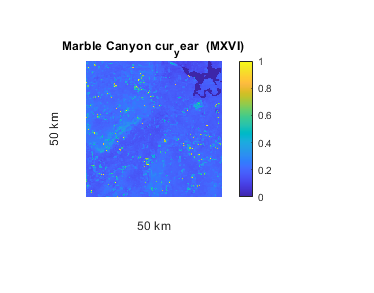

cur_name = "Teays Valley cur_year  (MXVI)"

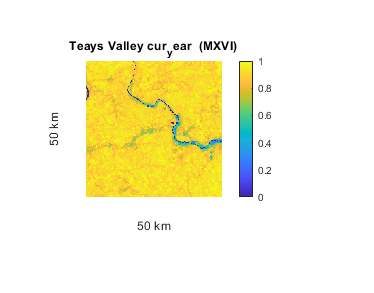

cur_name = "Oljato Monument Valley cur_year  (MXVI)"

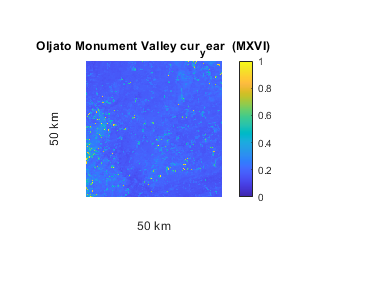

cur_name = "Sentinel Mesa cur_year  (MXVI)"

cur_name = "Grand Mesa cur_year  (MXVI)"

cur_name = "Mount Hood cur_year  (MXVI)"

cur_name = "Mount Helen cur_year  (MXVI)"

cur_name = "Mount Rainier cur_year  (MXVI)"

cur_name = "Black Canyon of the Gunnison cur_year  (MXVI)"

cur_name = "Gunnison Point cur_year  (MXVI)"

cur_name = "Marble Canyon cur_year  (MXVI)"

cur_name = "Teays Valley cur_year  (MXVI)"

cur_name = "Oljato Monument Valley cur_year  (MXVI)"

cur_name = "Sentinel Mesa cur_year  (MXVI)"

cur_name = "Grand Mesa cur_year  (MXVI)"

cur_name = "Mount Hood cur_year  (MXVI)"

cur_name = "Mount Helen cur_year  (MXVI)"

cur_name = "Mount Rainier cur_year  (MXVI)"

cur_name = "Black Canyon of the Gunnison cur_year  (MXVI)"

cur_name = "Gunnison Point cur_year  (MXVI)"

cur_name = "Marble Canyon cur_year  (MXVI)"

cur_name = "Teays Valley cur_year  (MXVI)"

cur_name = "Oljato Monument Valley cur_year  (MXVI)"

cur_name = "Sentinel Mesa cur_year  (MXVI)"

cur_name = "Grand Mesa cur_year  (MXVI)"

for year_i = 1:m_year_count
    cur_year = int2str(i + 2001);
    mkdir('Scene Maps/MXVI', [cur_year]);
    for scene_i = 1:m_scene_count
       cur_name = m_scene_names(scene_i);
       cur_file = append('Scene Maps/MXVI/', cur_year, '/', cur_name);
       cur_name = append(cur_name, ' cur_year ', ' (MXVI)')
       cur_fig = figure; cur_axes = gca; 
       cur_image = imshow(m_mxvi_subset{year_i, scene_i}, 'Colormap', parula(256));
       colorbar;
       xlabel('50 km');
       ylabel('50 km');
       title(cur_axes, cur_name);
       savefig(cur_fig, [cur_file]);
    end
    
end

clearvars -regexp cur_;
clearvars i j scene_i year_i;

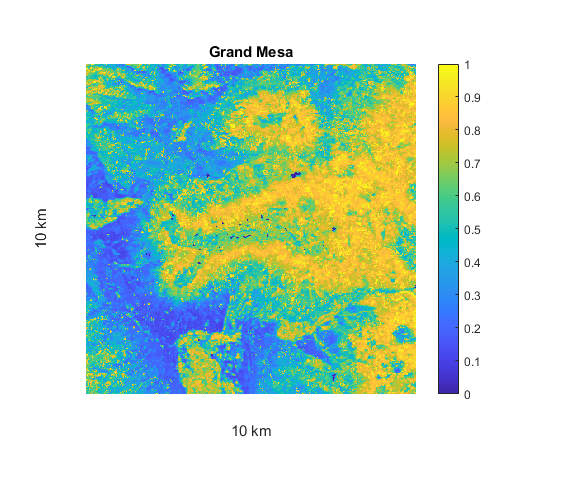

Not enough input arguments.

Error in gcd (line 4)
    at_index1 = [lat_vector(1), lon_vector(1)];

Error in map.rasterref.internal.simplifyRatio>simplify (line 39)
g = gcd(num, den);

Error in 